I. Implementation of XOR encryption

fs = 8000;
key = randi(255,80000,1,'uint8');
xlswrite('key.xlsx',key);

II. Recording voice

rec = audiorecorder

rec =   audiorecorder with properties:

       SampleRate: 8000
    BitsPerSample: 8
      NumChannels: 1
         DeviceID: -1
    CurrentSample: 1
     TotalSamples: 0
          Running: 'off'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audiorecorder'


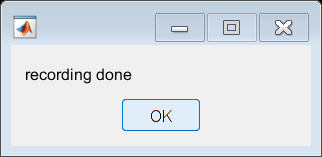

msg1 = msgbox('recording for 10 sec');
recordblocking(rec,10);
delete(msg1);
msg2 = msgbox('recording done');

III. Get data from recorded voice

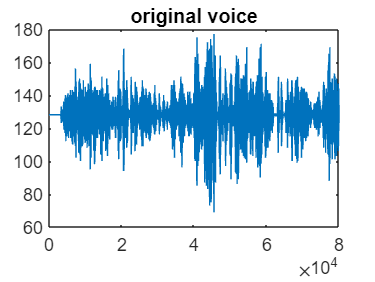

y = getaudiodata(rec,'uint8');
yp = getaudiodata(rec);
figure(1);
plot(y); title('original voice');

xlswrite('original_voice.xlsx',y);

IV. playing the original voice

sound(yp,fs)

V. Encrypting voice

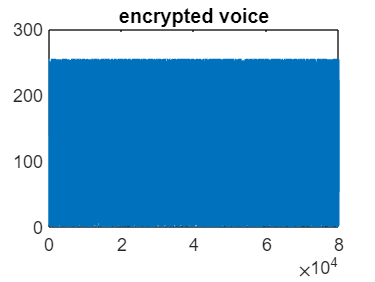

z = bitxor(y,key);
figure(2);
plot(z); title('encrypted voice');

e = audioplayer(z,fs);
xlswrite('encrypted_voice.xlsx',z);
audiowrite('encrypted_voice.wav',z,fs);

VI. playing the encrypted voice

play(e)



VII. Encrypted voice and key file

fs = 8000;
fprintf('upload the encrypted voice data\n');

upload the encrypted voice data


en = uigetfile('*.xlsx');
enc = xlsread(en);
encr = uint8(enc);

fprintf('upload the key\n');

upload the key


k = uigetfile('*.xlsx');
ke = xlsread(k);
key = uint8(ke);

VIII. Decrypting voice

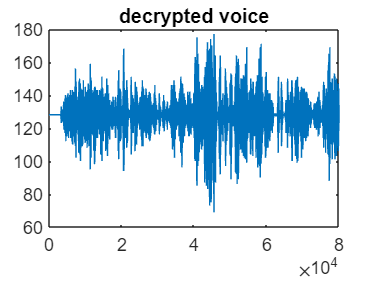

dec = bitxor(encr,key);
plot(dec); title('decrypted voice');

d = audioplayer(dec, fs);
xlswrite('decrypted_voice.xlsx',dec);

play(d)